    "ChatEA: "    "Hey there! It looks like we're in an 'industrial area' with a probability of 28 percent. This prediction is influenced by features like poles, driveways, and sky, which are crucial for identifying industrial zones. The model might be uncertain due to a lack of strong indicators like pavement or pedestrian presence."



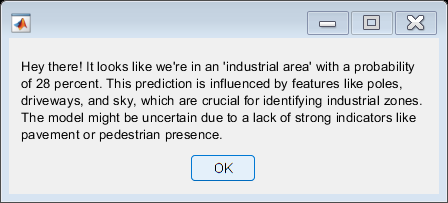

    "ChatEA: "    "Hey! The prediction of an 'industrial area' was likely influenced by the presence of poles, driveways, and the sky in the environment, as indicated by their high feature importance values. However, the model might not be very confident due to the absence of key features like pavement or pedestrian activity that would provide more certainty in the classification."



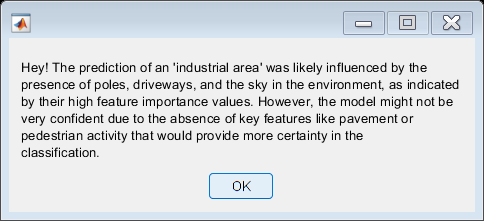

    "ChatEA: "    "In an industrial area, you would typically see more poles, driveways, and buildings, whereas a parking lot might have fewer poles and more cars. The presence of trees and fences could also differentiate between the two, with an industrial area having more structures like fences compared to a parking lot."



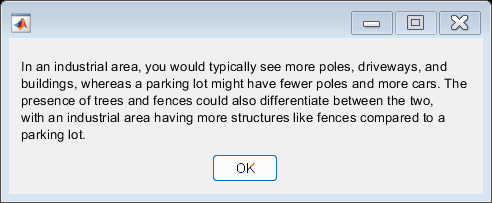

    "ChatEA: "    "I'm currently unable to provide the exact number of cars, but based on the detected features, we may expect a moderate number of cars in an industrial area. However, it's always important to remain cautious of traffic and pedestrian activity in such environments. Let me know if you need more information!"



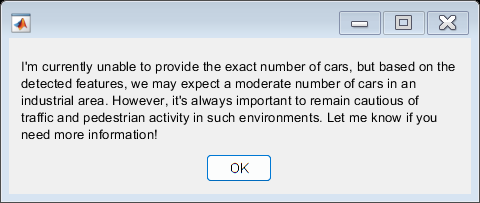

    "ChatEA: "    "You're welcome! If you have any more questions or need further assistance, feel free to ask. Enjoy the journey!"



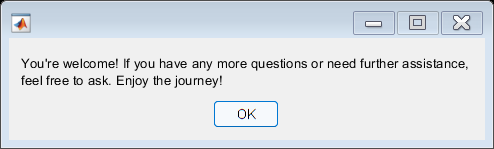

Goodbye!


% Create an instance of openAIChat
apiKey = 'YOUR_API_KEY';  % Replace 'YOUR_API_KEY' with your actual API key
chatInstance = openAIChat('ApiKey', apiKey);
% Initialize an empty cell array to store conversation history
conversationHistory = {};

% Specify the RAG file name
fileName = '0006R0_f01380_industrial area.csv';
[~, filename, ~] = fileparts(fileName);

% Read the content of the file into a string variable
fileContent = fileread(fileName);
fileContent =string (fileContent);

% Add the table content to the conversation history
conversationHistory{end+1} = fileContent;

all_responses = {};

addSystemMessage = "You are an AI model designed to adapt to various scenarios in autonomous driving. You have the details like predicted class, alternative predictions (contrastive cases), probabilities, feature importance, and how certain factors affect predictions. When engaging with user queries, focus on the specific question, provide concise explanations within a 50-word limit, and use friendly language. Identify key causal connections and highlight abnormal values that significantly contribute to the prediction, explaining their relevance in driving scenarios. Here’s an example of how you could respond to user questions: USER: The display panel just showed ‘residential neighbourhood’ on the screen. It didn’t seem pretty confident. YOU (accessing relevant data): Hey there! It looks like we’re in a ‘residential neighbourhood’ right now with a probability of 40 percent. This means we're on a road surrounded by features like driveways, sidewalks, trees, and cars, which are highly influential (with high importance values) to this observation. USER: Cool! I am just curious, what happens if there was no sidewalk? YOU (accessing relevant data for feature impact on the predicted class and the contrastive case): If the environment looked more like a freeway with no sidewalks, the ‘residential neighbourhood’ would be less likely (drop to 20 percent); in contrast, it would increase the probability for ‘highway’ (alternative prediction) to 13 percent. USER: Interesting! Can you tell me how ‘residential neighbourhood’ and ‘highway’ differ in their features? YOU (comparing most important features): Sure! Both places have buildings and cars, but the sidewalks and trees are strong clues for a neighbourhood. USER: How many cars are there? YOU: I'm sorry, but I'm currently unable to provide the exact number of cars. However, based on the detected features, we're in a residential area where I should be extra cautious for pedestrians and potentially slower speeds compared to major roads. Is that a sufficient explanation? USER: Yes, thanks! YOU: You're welcome! If you have any more questions or need assistance with " + ...
    "anything else, feel free to ask. Enjoy the ride!";

conversationHistory{end+1} = addSystemMessage;

while true
    % Get user input for userMessage
    user_q = input('User: ', 's');  % 's' specifies that the input should be treated as a string

    % Exit the loop if the user enters a specific command (e.g., 'exit')
    if strcmpi(user_q, 'Thanks')
        disp('Goodbye!');
        break;
    end

    if ischar(user_q)
        user_q = string(user_q);
    end

    % Add the user's input to the conversation history
    conversationHistory{end+1} = user_q;

    % Generate a response using the OpenAI API
   prompt = strjoin(string(conversationHistory), ' ');

    [text, message, response] = chatInstance.generate(prompt);

    % Add the AI's response to the conversation history
    conversationHistory{end+1} = text;

    all_responses{end+1} = text; 
    % Display the generated response
    disp(['ChatEA: ' text]);
    h = msgbox(text);
end

save chat history


% Specify the file name
chatHist=conversationHistory;
chat_folder='..\chat_hist';

fileTxt = fullfile(chat_folder, sprintf('%s.txt', filename));
%fileTxt = 'parking lot3.txt';

% Open the file for writing
fileID = fopen(fileTxt, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Error opening the file for writing.');
end

% Loop through each element of the cell array and write it to the file
for i = 1:numel(chatHist)
    fprintf(fileID, '%s\n\n', chatHist{i});
end


% Close the file
fclose(fileID);

Save only responses

% Extract responses 4, 6, 8, and 10
%all_responses = conversationHistory([4, 6, 8, 10]);

ans_folder='..\answers';

ansTxt = fullfile(ans_folder, sprintf('%s.txt', filename));
%fileTxt = 'parking lot3.txt';

% Open the file for writing
fileID2 = fopen(ansTxt, 'w');

% Check if the file was opened successfully
if fileID2 == -1
    error('Error opening the file for writing.');
end

% Loop through each element of the cell array and write it to the file
for i = 1:numel(all_responses)
    fprintf(fileID2, '%s\n\n', all_responses{i});
end


% Close the file
fclose(fileID2);
